## **Przetwarzanie Sygnałów Cyfrowych**

# **Parametry sygnalow cyfrowych**

## Jan Rosa 410269 AiR

### Zad 1

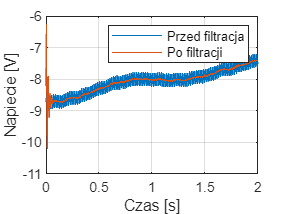

% wczytywanie pliku
figure
load openloop60hertz, openLoop=openLoopVoltage;
Fs=1000;
t=(0:length(openLoop)-1)/Fs;
plot(t, openLoop); box on; grid on;
ylabel 'Voltage [V]', xlabel 'Time [s]'
title 'Open-Loop Voltage with Noise'
%% Power spectrum - Moc
%% na ok 60 Hz widzimy 
figure;
periodogram(openLoop, [], [], Fs);
%% Projektujemy filtr
filtCoeff= designfilt('bandstopiir', 'FilterOrder', 2,...
'HalfPowerFrequency1', 50, 'HalfPowerFrequency2', 70, ...
'SampleRate', Fs);
%% Wykres filtru
%fvtool(filtCoeff)
noiseFreeSignal= filter(filtCoeff, openLoop);
%% sprawadzamy wynik w dziedzinie czasu
close all;
figure;
plot (t, openLoop, t, noiseFreeSignal); grid on;
legend('Przed filtracja', 'Po filtracji');
ylabel 'Napiecie [V]', xlabel 'Czas [s]'

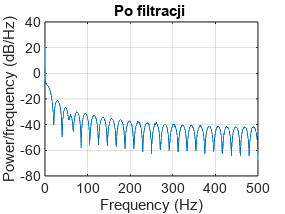

%% sprawdzamy wynik w dziedzinie częstotliwości
figure;
periodogram(noiseFreeSignal, [], [], Fs);
title('Po filtracji ');

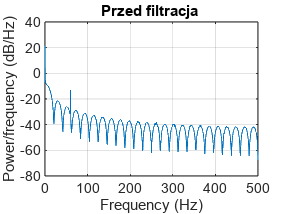

figure;
periodogram(openLoop, [], [], Fs);
title('Przed filtracja ');
hold off;

### Zad 2

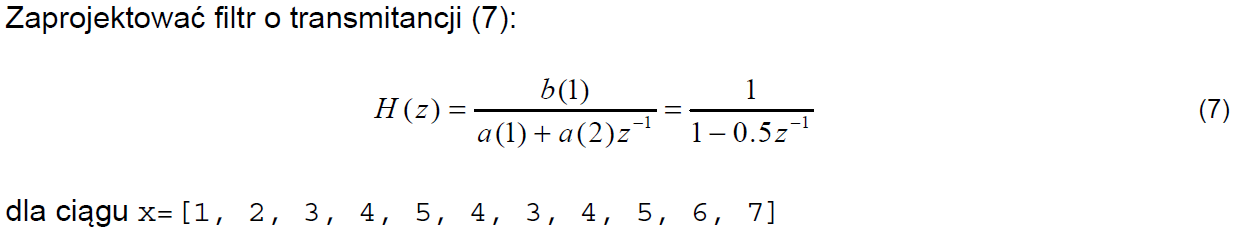

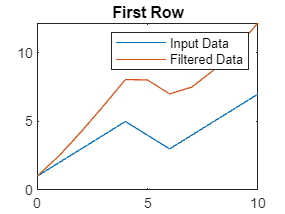

figure
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = 1;
a = [1 -0.5];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data')

title('First Row')

### Zad 3

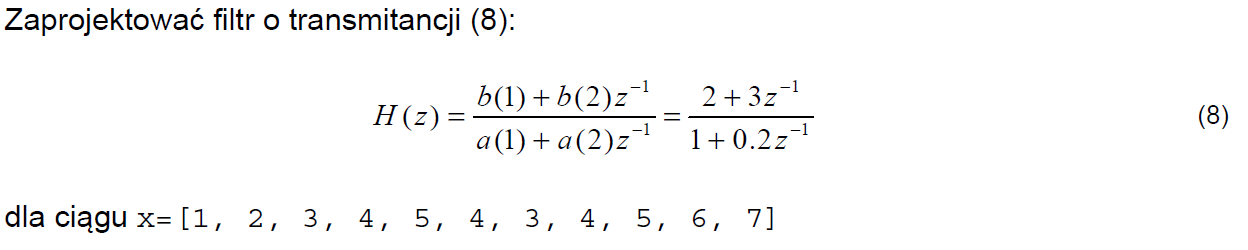

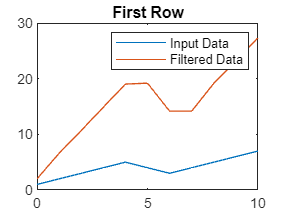

figure
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = [2 3];
a = [1 0.2];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data')
title('First Row')

### Zad 4

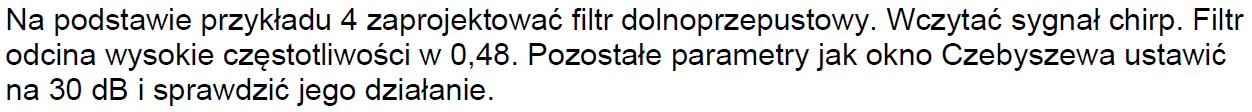

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
bhi = fir1(34,0.48,'high',chebwin(35,30));
freqz(bhi,1)
fvtool(bhi)
outhi = filter(bhi,1,y);
xfft=abs(fft(outhi));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,1,2)
plot(t,outhi)
title('Highpass Filtered Signal')
xlabel('Time (s)')
ylim(ys)

### Zad 5

### Zad 3

### Zad 3

### Zad 3

### Zad 3

### Zad 3

### Zad 3

### Zad 3

### Zad 3

### Zad 3

### Zad 3

### Zad 3

### Zad 3